# Basket

Use MATLAB with Python to play with NBA data

**Resources**

- [https://github.com/swar/nba_api](https://github.com/swar/nba_api) 

### Games

games = readtable("games-2015-2024.csv")

games = 10749x8 table
    GAME_ID     GAME_DATE         MATCHUP         WL      PTS    PLUS_MINUS     TEAM      OPPONENT
    ________    __________    _______________    _____    ___    __________    _______    ________

    2.15e+07    2015-10-27    {'CHI vs. CLE'}    {'W'}     97         2        {'CHI'}    {'CLE'} 
    2.15e+07    2015-10-27    {'ATL vs. DET'}    {'L'}     94       -12        {'ATL'}    {'DET'} 
    2.15e+07    2015-10-27    {'GSW vs. NOP'}    {'W'}    111        16        {'GSW'}    {'NOP'} 
    2.15e+07    2015-10-28    {'PHX vs. DAL'}    {'L'}     95       -16        {'PHX'}    {'DAL'} 
    2.15e+07    2015-10-28    {'POR vs. NOP'}    {'W'}    112        18        {'POR'}    {'NOP'} 
    2.15e+07

% Initialize constants
K = 20;
HOME_EDGE = 100;

% Unique teams
teams = unique(games.TEAM);
elo = struct();

% Initialize Elo ratings
for i = 1:length(teams)
    team = teams{i};
    elo.(team) = 1500;
end

% Prepare records
records = [];

% Sort games by date
games = sortrows(games, 'GAME_DATE');

for i = 1:height(games)
    row = games(i, :);
    team = row.TEAM{1};
    opp  = row.OPPONENT{1};
    gid = row.GAME_ID;
    date = row.GAME_DATE;
    
    % Ensure both teams exist in struct
    if ~isfield(elo, tname), elo.(tname) = 1500; end
    if ~isfield(elo, oname), elo.(oname) = 1500; end

    % Elo before the game (add home edge)
    r_team = elo.(tname) + HOME_EDGE;
    r_opp  = elo.(oname);
    
    % Win or lose (1 or 0)
    y = strcmp(row.WL, 'W');
    
    % Store record
    record = table(...
        date, gid, ...
        {team}, {opp}, ...
        elo.(tname), elo.(oname), ...
        r_team - r_opp, y, ...
        'VariableNames', {'date','game_id', ...
                          'team', 'opponent', ...
                          'elo_pre', 'elo_opp_pre', ...
                           'elo_diff', 'win'});
    records = [records; record];

    % Update Elo ratings
    exp_t = 1 / (1 + 10^((r_opp - r_team)/400));
    exp_o = 1 / (1 + 10^((r_team - r_opp)/400));
    
    elo.(tname) = elo.(tname) + K * (y - exp_t);
    elo.(oname) = elo.(oname) + K * ((1 - y) - exp_o);
end

% Output final records
records

records = 10749x8 table
       date       game_id      team      opponent    elo_pre    elo_opp_pre    elo_diff     win 
    __________    ________    _______    ________    _______    ___________    ________    _____

    2015-10-27    2.15e+07    {'CHI'}    {'CLE'}       1500         1500           100     true 
    2015-10-27    2.15e+07    {'ATL'}    {'DET'}     1507.2       1492.8         114.4     false
    2015-10-27    2.15e+07    {'GSW'}    {'NOP'}       1494         1506         88.04     true 
    2015-10-28    2.15e+07    {'PHX'}    {'DAL'}     1501.5       1498.5        103.08     false
    2015-10-28    2.15e+07    {'POR'}    {'NOP'}     1488.7       1511.3        77.313     true 
    2015-10-28    2.15e+

### Prep data

% Feature matrix (X) and target vector (y)
X = records(:, {'elo_pre', 'elo_opp_pre', 'elo_diff'});
y = records.win;

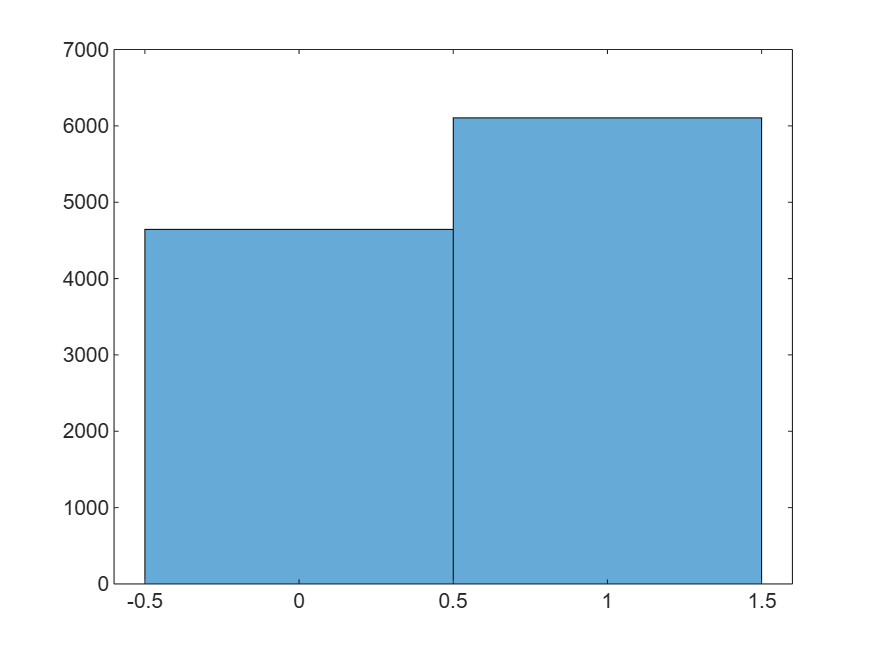

histogram(y)

### Classification

classificationLearner

The models are overpredicting wins, probably because the dataset is unbalanced